# Zero-forcing Beamformer Implementation and Comparison

## Parameters

M = 3;                  % no. of antennas
N = 20;                 % no. of samples
Delta = 1/2;            % spacing b/w antennas (in terms of wavelength)
theta = [-20, 30];      % directions of sources (in degrees) (-90 to 90)
f = [0.1, 0.12];        % normalized frequency (b/w 0 and 1)
d = length(theta);      % no. of sources
SNR = 10;               % in dB

### Data generation

[X, A, S] = gendata(M, N, Delta, theta, f, SNR);

## ESPRIT for direction, frequency estimation

theta_est = esprit(X, d);
fprintf('True angles: %s degrees\n', mat2str(theta, 4));

True angles: [-20 30] degrees


fprintf('Estimated angles: %s degrees\n', mat2str(theta_est', 4));

Estimated angles: [-18.54 27.38] degrees



f_est = espritfreq(X, d);
fprintf('True frequencies: %s\n', mat2str(f, 4));

True frequencies: [0.1 0.12]


fprintf('Estimated frequencies: %s\n', mat2str(f_est', 4));

Estimated frequencies: [0.09128 0.1212]


## Functions to create vectors

### a) For a given angle - steering vector

steering_vector = @(angle_deg, M, Delta) exp(-1j * 2 * pi * Delta * (0:M-1)' * sind(angle_deg));

### b) For a given frequency - temporal signature vector

temporal_vector = @(freq, N) exp(1j * 2 * pi * freq * (0:N-1));

## Estimated matrices for zero-forcing

### a) Based on DoA - estimated steering matrix

A_est_doa = zeros(M, d);
for i = 1:d
    A_est_doa(:, i) = steering_vector(theta_est(i), M, Delta);
end

### b) Based on frequency - estimated temporal signature matrix

S_est_freq = zeros(d, N);
for i = 1:d
    S_est_freq(i, :) = temporal_vector(f_est(i), N);
end

## Zero-forcing beamformers

W_doa = ((A_est_doa' * A_est_doa) \ A_est_doa')'; % for estimating S given estimates of A
W_freq = (S_est_freq * X' / (X * X'))'; % for estimating A given estimates of S

### Applying to noiseless data for verification

X_noiseless = A * S;
S_est_doa = W_doa' * X_noiseless;
A_est_freq = pinv(W_freq');
S_est_freq_ = W_freq' * X_noiseless;

% verifying recovery
fprintf('DOA beamformer MSE: %e\n', mean(abs(S_est_doa(:) - S(:)).^2));

DOA beamformer MSE: 1.879376e-02


fprintf('Frequency beamformer MSE: %e\n', mean(abs(S_est_freq_(:) - S(:)).^2));

Frequency beamformer MSE: 2.072902e-01


## Spatial responses

theta_grid = -90:0.5:90;
response_doa = zeros(length(theta_grid), d);
response_freq = zeros(length(theta_grid), d);

### Spatial responses for DoA-based beamformer

for i = 1:d
    w_doa_i = A_est_doa(:, i);
    for j = 1:length(theta_grid)
        a_theta = steering_vector(theta_grid(j), M, Delta);
        response_doa(j, i) = abs(w_doa_i' * a_theta);
    end
end

### Spatial responses for frequency-based beamformer

for i = 1:d
    w_freq_i = A_est_freq(:, i);
    for j = 1:length(theta_grid)
        a_freq = steering_vector(theta_grid(j), M, Delta);
        response_freq(j, i) = abs(w_freq_i' * a_freq);
    end
end

### Plotting

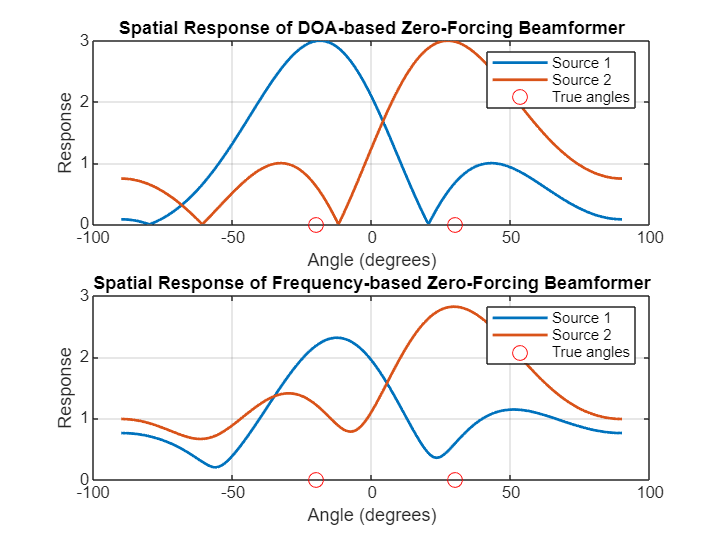

figure(1);

subplot(2, 1, 1);
plot(theta_grid, response_doa, 'LineWidth', 1.5);
grid on;
title('Spatial Response of DOA-based Zero-Forcing Beamformer');
xlabel('Angle (degrees)');
ylabel('Response');
hold on;
plot(theta, zeros(size(theta)), 'ro', 'MarkerSize', 8);
legend('Source 1', 'Source 2', 'True angles');
hold off;

subplot(2, 1, 2);
plot(theta_grid, response_freq, 'LineWidth', 1.5);
grid on;
title('Spatial Response of Frequency-based Zero-Forcing Beamformer');
xlabel('Angle (degrees)');
ylabel('Response');
hold on;
plot(theta, zeros(size(theta)), 'ro', 'MarkerSize', 8);
legend('Source 1', 'Source 2', 'True angles');
hold off;